% Define the objective function f for maximizing ATP production (in units of pmol/min/ug protein)
f=[0 0 0 2 0 0 2.5 0 0 0 0 0 0 0 0 0 7.5];

% Additional constraint matrix A; the sum of JO2 fluxes (oxygen flux)
A=[0 0 0 0 0 0 0.5 0 0 0 0 0 0 0 0 0 1.5];

% Vector b for the constraint; the measured JO2 (oxygen flux) value
b=[800];

% Equality constraint matrix Aeq, describing stoichiometries in metabolic reactions
Aeq=[1 0 0 0 -1 1 0 0 0 0 0 0 1 -1 0 0 0;
    0 1 0 0 0 0 0 0 0 1 -1 -1 1 0 0 0 0;
    0 0 1 -1 0 0 0 0 0 0 0 0 0 0 0 0 0;
    0 0 0 0 1 -1 -1 1 0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 1 -1 -1 1 0 0 0 0 0 0 -1;
    0 0 0 0 0 0 0 0 0 0 0 0 1 -1 -1 1 0;
    0 0 0 2 0 0 0 0 0 0 1 -1 -1 1 0 0 0];

% Equality constraint vector beq, steady-state assumption makes these zero
beq=zeros([1 7]);

% Lower bounds for flux variables; all zeros mean that all fluxes are non-negative
lb= zeros ([1 17]);

% Upper bounds for flux variables; experimentally limited values
ub=[1000 0 0 1000 500 0 1000 0 1000 0 1000 0 1000 0 1000 0 0];

% Run linear programming to maximize -f (since MATLAB minimizes by default)
F=linprog(-f, A, b, Aeq, beq, lb, ub);

Optimal solution found.



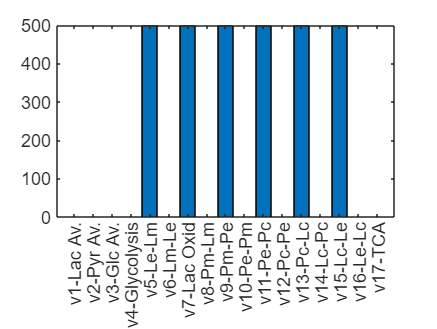


% Compute the optimized objective function value by taking the dot product with original f
O=dot(F,f);

% Define category labels for metabolic fluxes
x = categorical({'v1-Lac Av.', 'v2-Pyr Av.', 'v3-Glc Av.', 'v4-Glycolysis', 'v5-Le-Lm', 'v6-Lm-Le', 'v7-Lac Oxid', 'v8-Pm-Lm', 'v9-Pm-Pe', 'v10-Pe-Pm', 'v11-Pe-Pc', 'v12-Pc-Pe', 'v13-Pc-Lc', 'v14-Lc-Pc', 'v15-Lc-Le', 'v16-Le-Lc', 'v17-TCA'});

% Reorder categories for plotting
x = reordercats(x,{'v1-Lac Av.', 'v2-Pyr Av.', 'v3-Glc Av.', 'v4-Glycolysis', 'v5-Le-Lm', 'v6-Lm-Le', 'v7-Lac Oxid', 'v8-Pm-Lm', 'v9-Pm-Pe', 'v10-Pe-Pm', 'v11-Pe-Pc', 'v12-Pc-Pe', 'v13-Pc-Lc', 'v14-Lc-Pc', 'v15-Lc-Le', 'v16-Le-Lc', 'v17-TCA'});

% Store the optimized flux values in variable y
y = (F);

% Create a bar graph for the optimized flux values
bar(x,y)